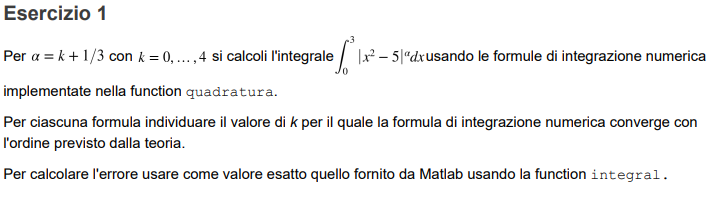

clear all
close all
k_=[0 1 2 3 4];
N = 100;
a = 0;
b = 3;
divs = [10 100 1000 10000 100000]

divs =           10         100        1000       10000      100000


div = 10

div = 100

div = 1000

div = 10000

div = 100000

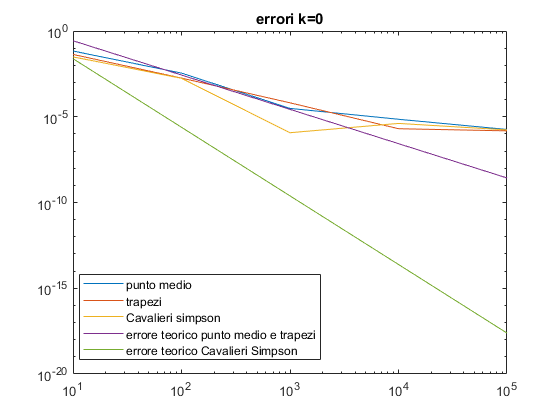

div = 10

div = 100

div = 1000

div = 10000

div = 100000

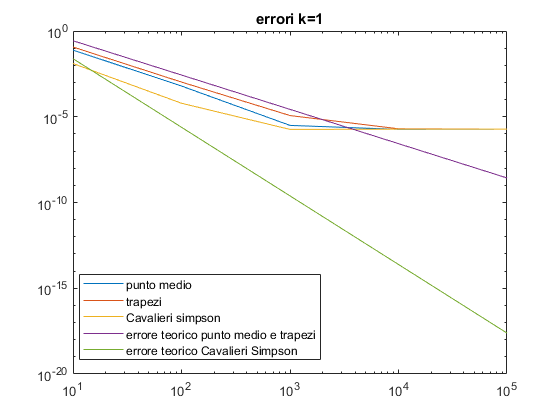

div = 10

div = 100

div = 1000

div = 10000

div = 100000

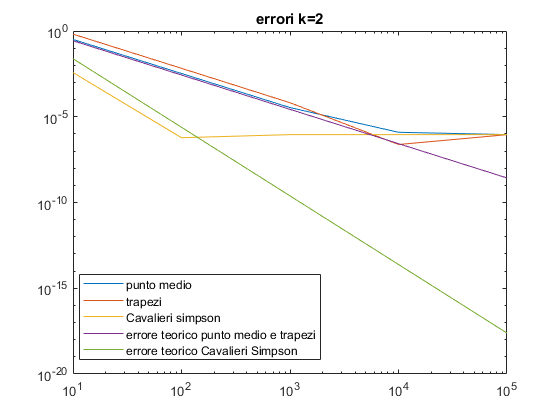

div = 10

div = 100

div = 1000

div = 10000

div = 100000

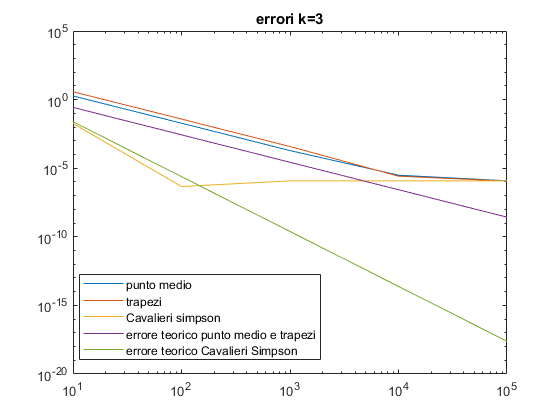

div = 10

div = 100

div = 1000

div = 10000

div = 100000

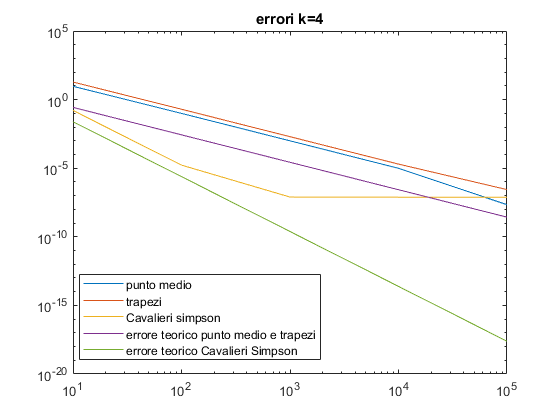

for k = k_
    alpha = k+1/3;
    f = @(x) abs(x.^2 - 5).^alpha;
    Ies=integral(f,a,b);
    E=[];
    H=[];
    for i=1:1:length(divs)
        %div=10*2^expo
        div =divs(i)
        for m=1:3
            I=quadratura(f,a,b,div,m);
            %E(expo,m)=abs(Ies-I);
            E(i,m)=abs(Ies-I);
        end
        H=[H (b-a)/div];
        %V(expo)=div;
        V(i)=div;
    end
    figure
    loglog(V,E(:,1))
    hold on
    loglog(V,E(:,2))
    loglog(V,E(:,3))
    loglog(V,H.^2*(b-a))
    loglog(V,H.^4*(b-a))
    title("errori k="+k)
    legend("punto medio","trapezi","Cavalieri simpson","errore teorico punto medio e trapezi","errore teorico Cavalieri Simpson",'Location','best')
end

punto medio k = 4

trapezi k = 4

Cavalieri simpson

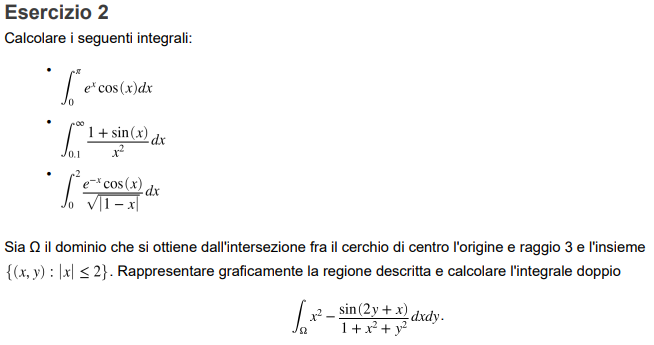

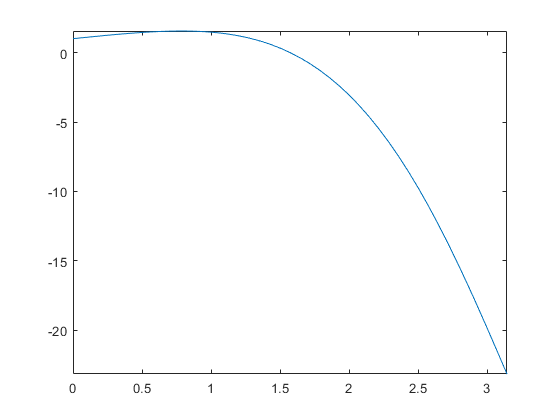

clear all
close all

f = @(x) exp(x).*cos(x); a=0; b = pi;
fplot(f,[a b])

I = integral(f,a,b)

I = -12.0703

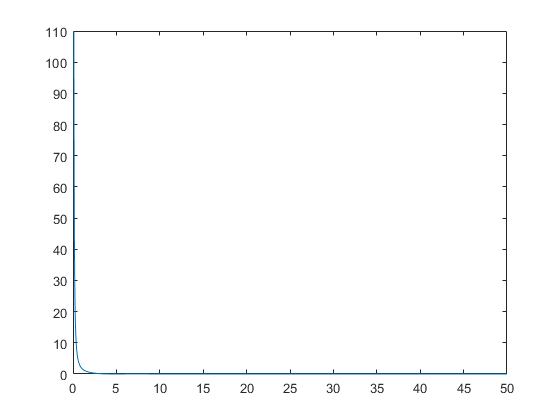

f = @(x) (1+sin(x))./(x.^2); a=0.1; b=+inf;
fplot(f,[a 50])

I = integral(f,a,b)

I = 12.7262

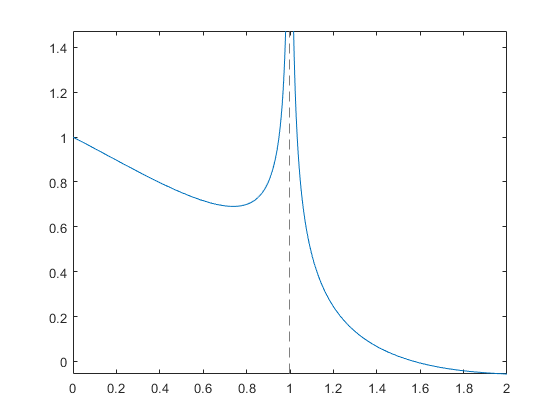

f = @(x) (exp(-x).*cos(x))./(sqrt(abs(1-x))); a=0; b=2;
fplot(f,[a b])

I = integral(f,a,b)

I = 1.0269

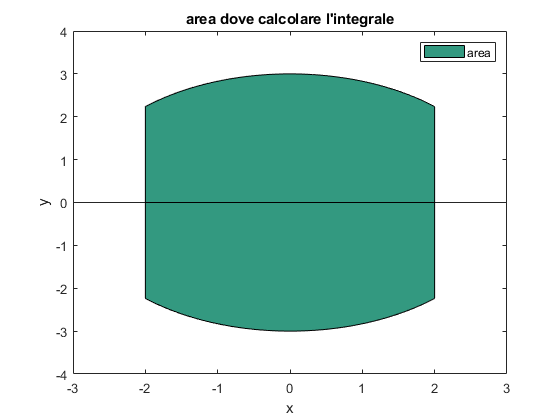




f = @(x) sqrt(9-x.^2);
f1 = @(x) -sqrt(9-x.^2);
t =-2:0.01:2;
a = area(t,f(t));
a.FaceColor = [0.2 0.6 0.5];
hold on
b = area(t,f1(t));
b.FaceColor = [0.2 0.6 0.5];
xlim([-3 3])
ylim([-4 4])
legend("area")
xlabel x
ylabel y
title("area dove calcolare l'integrale")
hold off

g = @(x,y) x.^2-(sin(2*y+x))./(1+x.^2+y.^2)

g = function_handle with value:
    @(x,y)x.^2-(sin(2*y+x))./(1+x.^2+y.^2)


I = integral2(g,-2,2,f1,f)

I = 27.3179

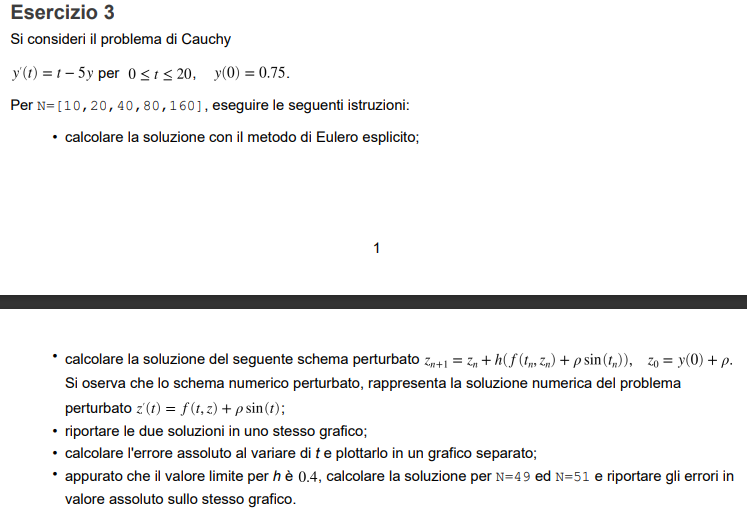

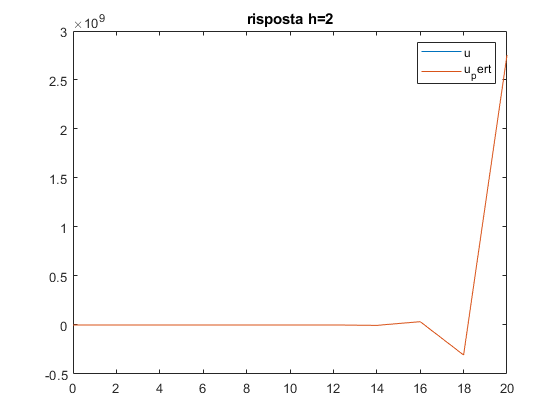

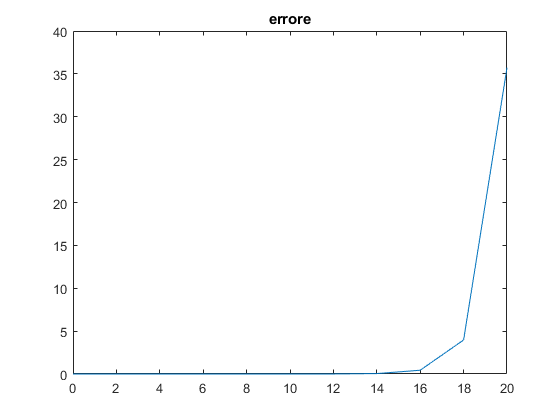

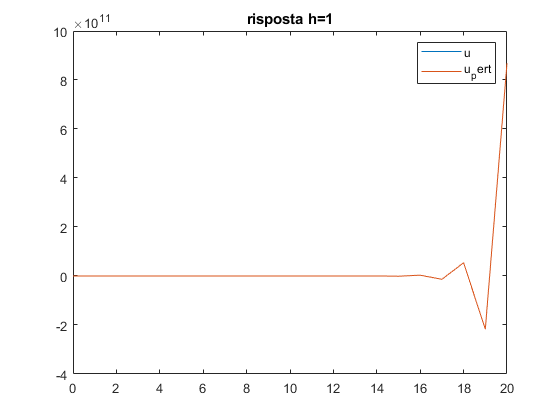

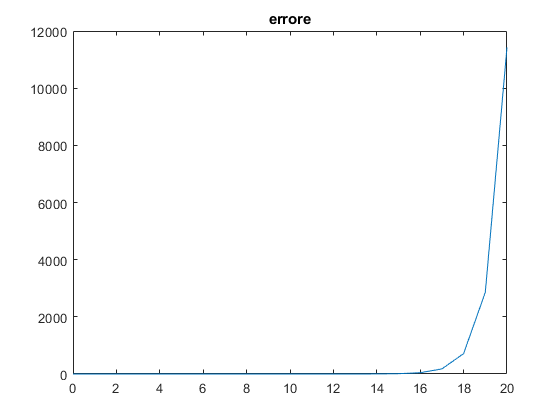

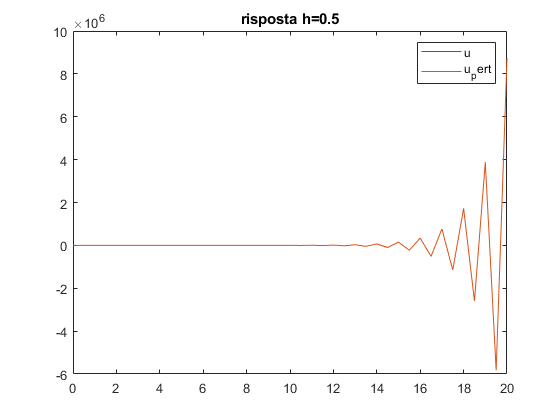

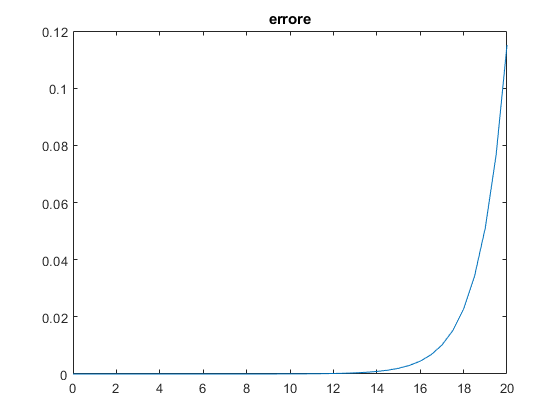

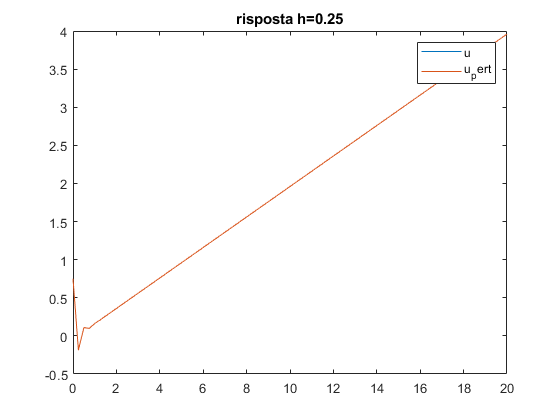

clear all
close all

p = 1e-8;
N = [10 20 40 80 160];
f = @(t,y) t-5*y;
f1 =@(t,y) t-5*y+p*sin(t);
H=[];
for n = N
    [tt,u,h]=euleroesp(f,0,20,0.75,n);
    [tt,u_pert]=euleroesp(f1,0,20,0.75+p,n);
    figure
    plot(tt,u,tt,u_pert)
    legend("u","u pert")
    title("risposta h=" +h)
    figure
    err = abs(u-u_pert);%errore in funzione del tempo
    plot(tt,err)
    title("errore")
    H = [H h];
end

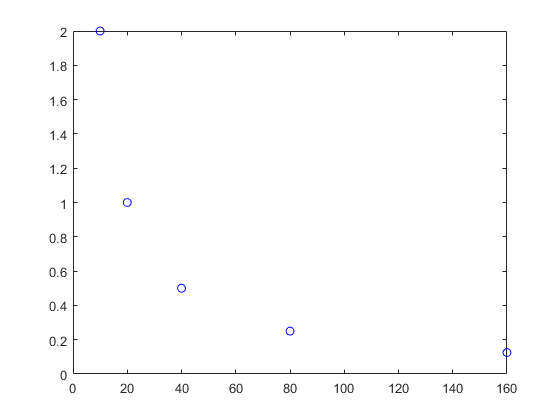

plot(N,H,'ob')

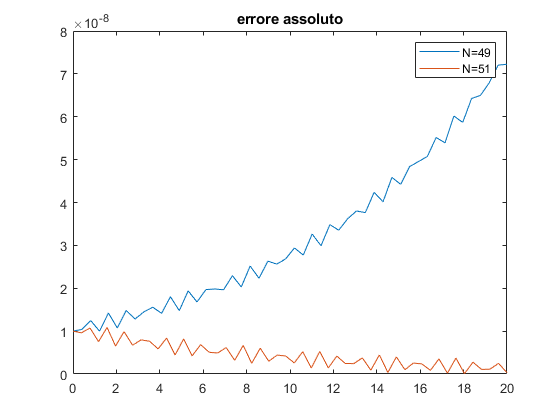




N=[49,51];
H=[];
for n=N
    [tn,un,h]=euleroesp(f,0,20,0.75,n);
    [tnp,unp]=euleroesp(f1,0,20,0.75+p,n);
    E=abs(unp-un);
    H=[H h];
    plot(tn,E)
    hold on
    title("errore assoluto")
end
legend("N=49","N=51")